Create a recorder object

fs = 22050;                                   % Sampling rate
nBits = 16;                                   % Number of bits per sample
nChannels = 1;                                % Number of channels
sRecord = audiorecorder(fs,nBits,nChannels);  % Create recorder object

Record your voice

%msgbox('Press button to start recording');
duration = 5;                                 % Recording duration in seconds
recordblocking(sRecord,duration);             % Record audio   
%msgbox('Recording finished. Press button to continue');

Graph audio data

x = getaudiodata(sRecord,'double');           % Create a vector with audio data
L = 2048;                                     % Delay amount for echo
r = 0.8;                                      % Gain factor for echo
buffer = zeros(L,1);                          % Buffer for ss_echof()
[y,buffer] = ss_echof(x,r,buffer);            % Add an echo
sound(y,fs);                                  % Play back modified recording

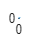

nSamp = length(x);
t = [1:nSamp]'/fs;                    % Create a time vector
plot(t,x); grid;
xlabel('Time (sec)');
ylabel('Amplitude');